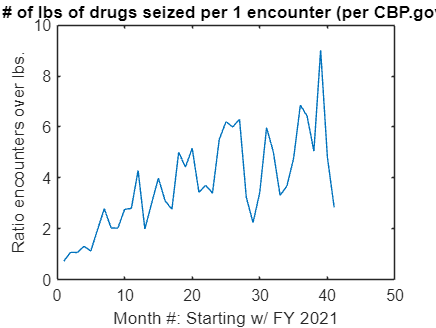

%% drug seizures (by thousands of lbs.)
drugfy21 = [98.2 66.8 68.9 59.8 89.3 87.8 64 88.6 93.3 77.2 74.8 44.7];
drugfy22 = [82.7 58.1 44.9 50 59.9 44.4 53.3 46.7 60.6 53.9 60 41.3];
drugfy23 = [37.3 39.2 40 48.5 69.8 56.2 35.5 41.1 43.6 49.9 48.9 39.3];
drugfy24 = [37.5 48 33.5 36.6 66.7];

%% border encounters (by thousands)
encfy21 = [71.929 72.113 73.994 78.414 101.099 173.277 178.795 180.597,... 
    189.034 213.593 209.840 192.001];

encfy22 = [164.837 174.845 179.235 154.874 166.01 222.574 235.785,... 
    241.136 207.834 200.162 204.087 227.547];

encfy23 = [231.529 235.173 252.315 157.358 156.63 193.249 211.992,... 
    206.69 144.556 183.479 232.963 269.735];

encfy24 = [240.932 242.408 301.982 176.204 189.922];

alldrugs = [drugfy21 drugfy22 drugfy23 drugfy24];
allenc = [encfy21 encfy22 encfy23 encfy24];

%% ratio for # of lbs of drugs per 1 encounter
rat = allenc ./ alldrugs;

xnew = {'Oct', 'Nov', 'Dec', 'Jan', 'Feb', 'Mar', 'Apr', 'May',... 
    'Jun', 'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec', 'Jan', 'Feb', 'Mar', 'Apr', 'May',... 
    'Jun', 'Jul', 'Aug', 'Sep','Oct', 'Nov', 'Dec', 'Jan', 'Feb', 'Mar', 'Apr', 'May',... 
    'Jun', 'Jul', 'Aug', 'Sep','Oct', 'Nov', 'Dec', 'Jan', 'Feb'};
%%linspace();
x = 1:1:41;
plot(x, rat);
title('# of lbs of drugs seized per 1 encounter (per CBP.gov)');
xlabel('Month #: Starting w/ FY 2021');ylabel('Ratio encounters over lbs.');


avg21new= sum(rat(1:12)) / 12;
avg22new= sum(rat(13:24)) / 12;
avg23new= sum(rat(25:36)) / 12;
avg24new= sum(rat(37:41)) / 5;
disp(avg21new);

    2.0024



disp(avg22new);

    3.7931



disp(avg23new);

    4.7552



disp(avg24new);

    5.6302

